clear
load data3.mat
n=length(data.CzasLokalnyUTC0100);
T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);
Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;
X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

locs=compressorCycles(X(1,:));
x = FeatureExtract(X(4,:),locs);
% plot((X(4,:)));hold on
% plot(locs,(X(4,locs)),'o');hold off
% title('Detection of peaks on Sonda temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')
f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);
% figure 
% subplot(311)
% plot(locs,f1,'o-')
% subplot(312)
% plot(locs,x(3,:),'o-')
% subplot(313)
% plot(locs,x(1,:)-x(2,:),'o-')

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
% plot(locs(1),(X(4,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0)
        % plot(locs(i-1):locs(i),(X(4,locs(i-1):locs(i))),"Color",'blue');
        % plot(locs(i),(X(4,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

% figure
% plot(X(4,indexContainer{1}))

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>2*60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

load TrainingDataset2
% parfor i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y{i},params{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
%         t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}));
% end
% save TrainingDataset2 y params

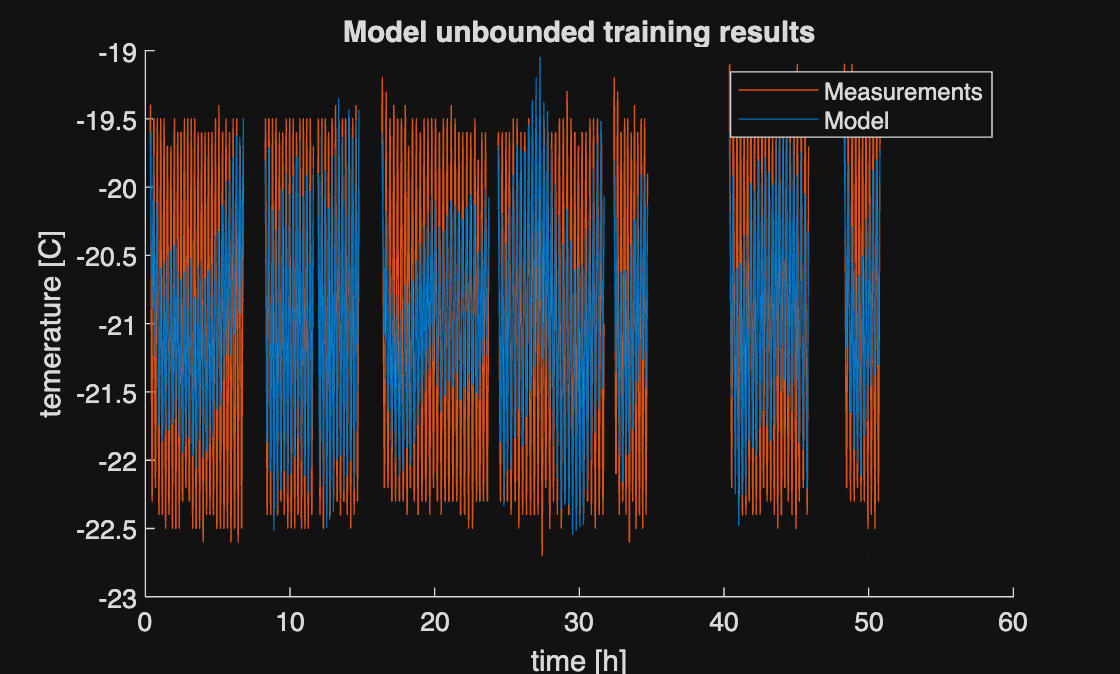

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

TrainingFraction=1;  % percent (form 0 to 1) of dataset used for training
TrainingNumber=floor(TrainingFraction*length(usableDataIndex));
TrainingData=usableDataIndex(1:TrainingNumber);
TestingData=usableDataIndex(TrainingNumber+1:end);

% function bestParameter=bestOfDataSet(TrainingSet,params,T)
TrainingSet=TrainingData;


averageRMSE=NaN(1,length(TrainingSet));
parfor j=1:length(TrainingSet) %for parameter set j
    RMSE_on_all=NaN(1,length(TrainingSet));
    for i=1:length(TrainingSet) %check rmse of j parameter set on all data chinks
        t_sim=T*(0:length(usableDataIndex{i})-1);
        RMSE_on_all(i) = costFunction(-X(1,usableDataIndex{i})', X(3,usableDataIndex{i})',...
            params{j}(1), params{j}(2), params{j}(3),...
            t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}));
    end

    if any(isnan(RMSE_on_all), 'all')
        error('Array RMSE_on_all contains NaN values.');
    end

    averageRMSE(j)=mean(RMSE_on_all); %average rmse for j parameter set on all data chunks

end

if any(isnan(averageRMSE), 'all')
    error('Array averageRMSE contains NaN values.');
end

[~,ind] = min(averageRMSE);
bestParameter=params(ind);

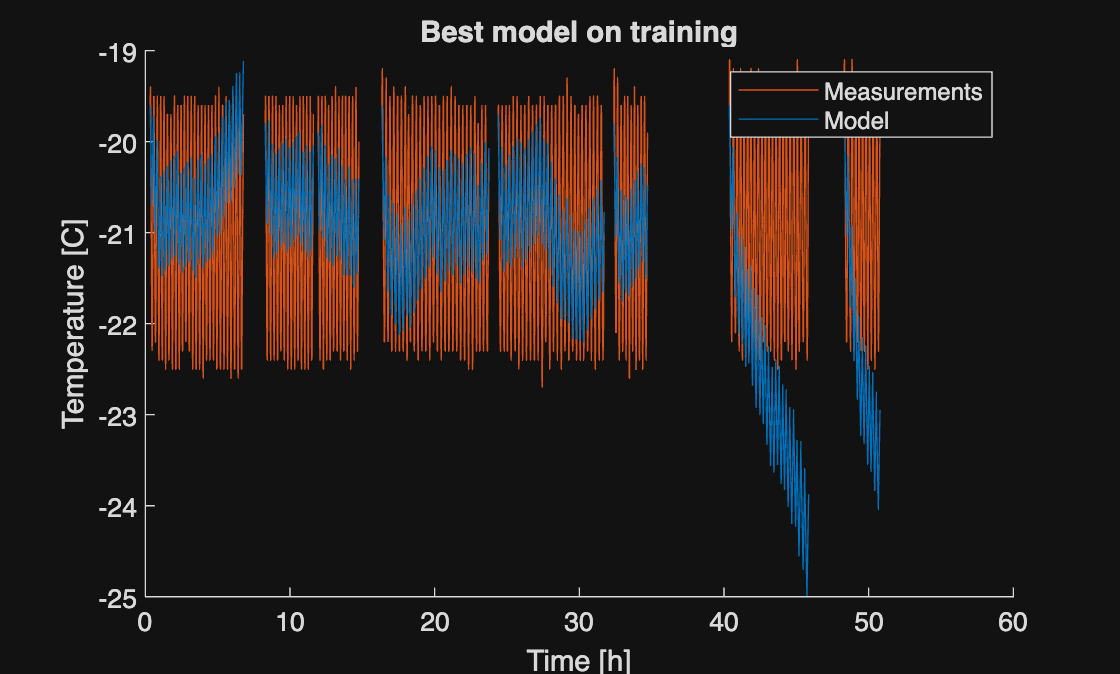

figure
hold on
for i = 1:TrainingNumber
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(1,usableDataIndex{i})', X(3,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X(4,usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

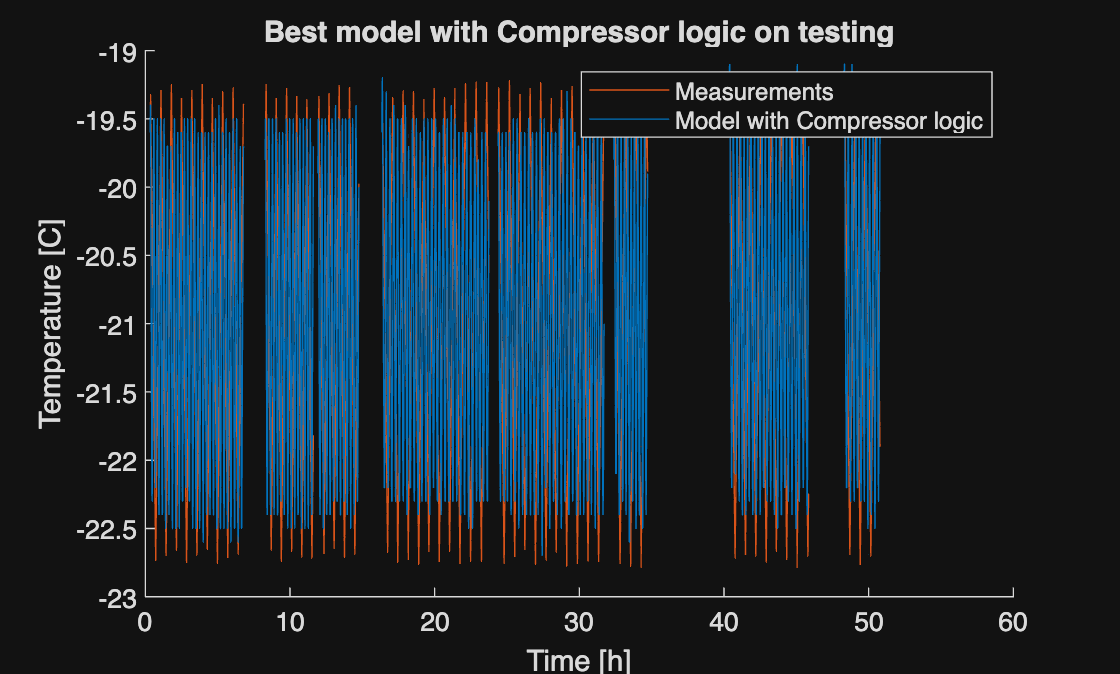

figure
hold on
count=1;
for i = 1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(1,usableDataIndex{i})', X(3,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X(4,usableDataIndex{i}(1)))';

    simData = fridge_fixed_stepCopy(X(3,usableDataIndex{i})',params{ind}(1), params{ind}(2), params{ind}(3),t_sim,X(4,usableDataIndex{i}(1))');
    plot(t(usableDataIndex{i})/(60*60),simData.y,'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#0072BD')
    compare_container.mask_pred{count}=simData.u1;
    compare_container.mask_meas{count}=-X(1,usableDataIndex{i});
    count=count+1;
    % plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
    clear simData
end
hold off
title('Best model with Compressor logic on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model with Compressor logic')

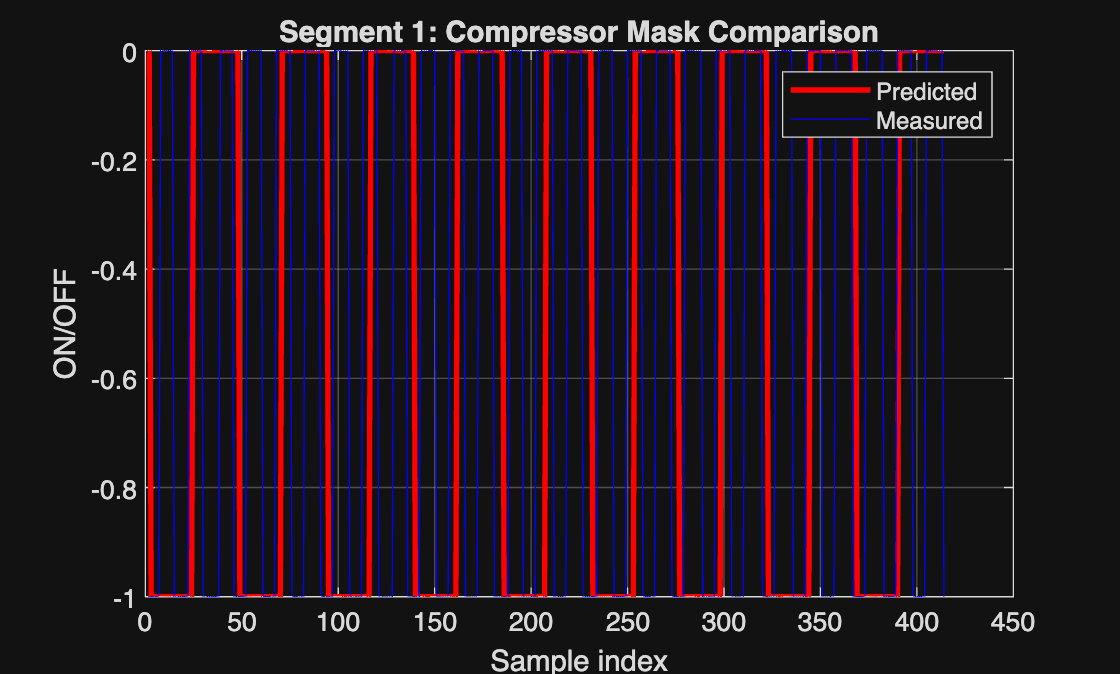

--- Segment 1 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = +2.0 s (1.0%)



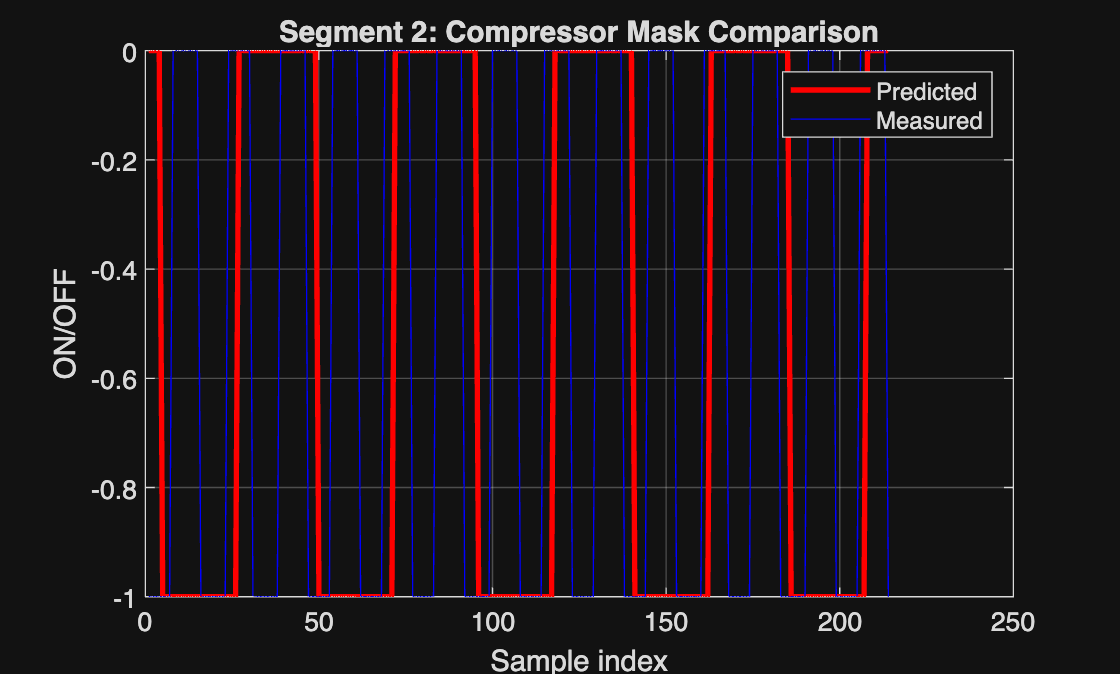

--- Segment 2 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +6.0 s (5.8%)



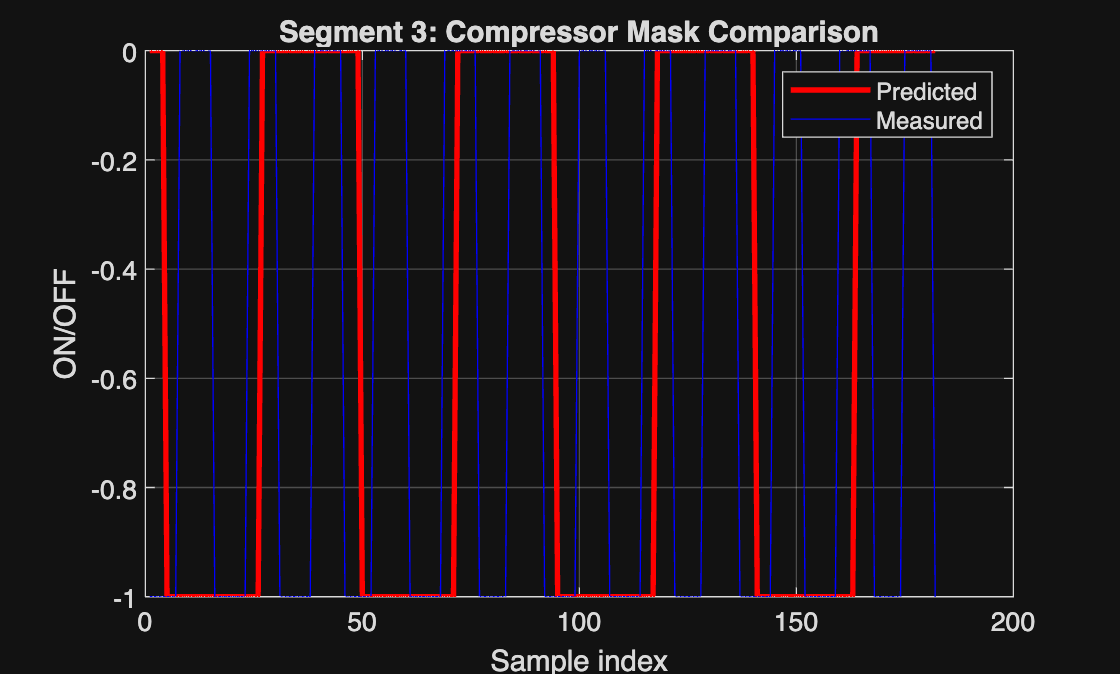

--- Segment 3 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -2.0 s (-2.2%)



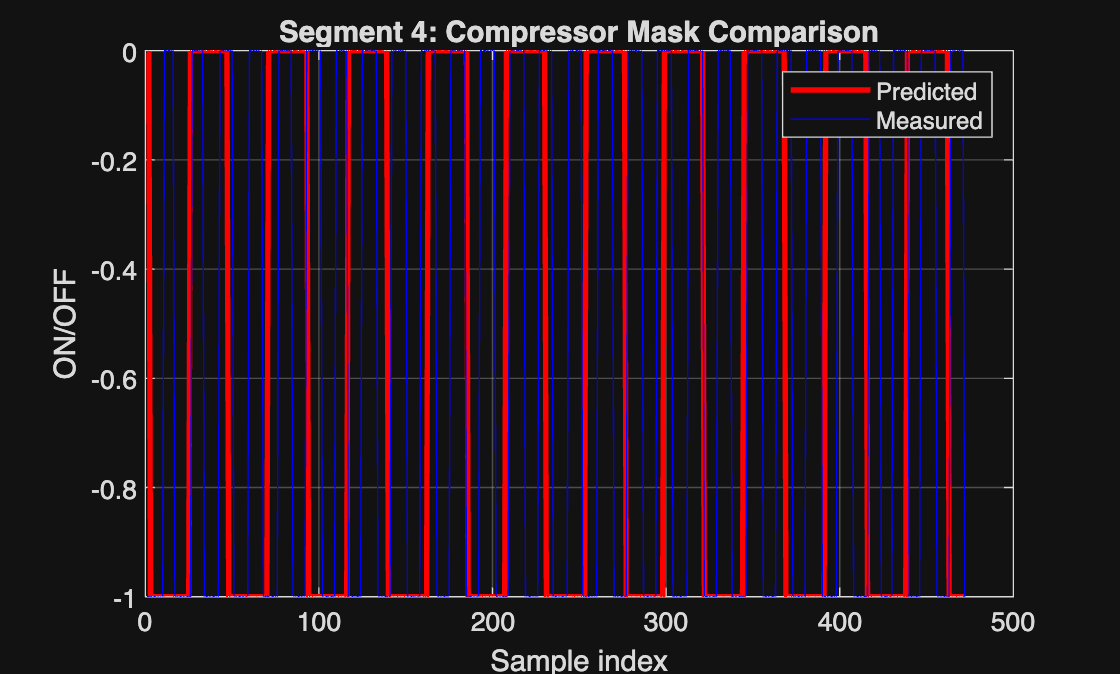

--- Segment 4 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = +2.0 s (0.8%)



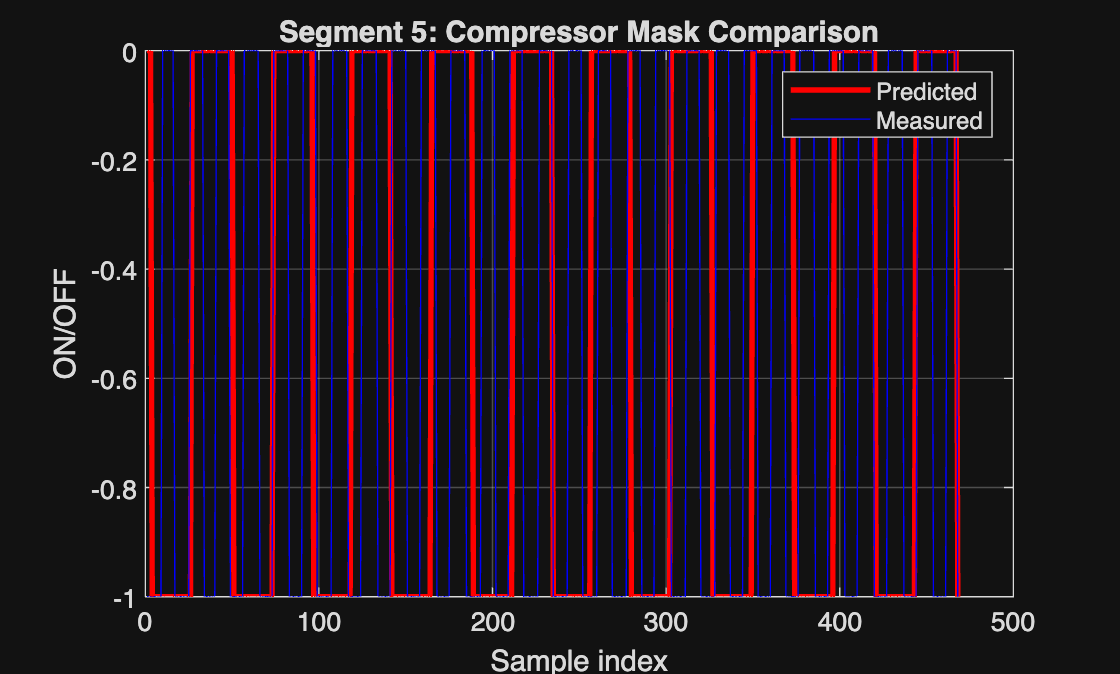

--- Segment 5 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -5.0 s (-2.1%)



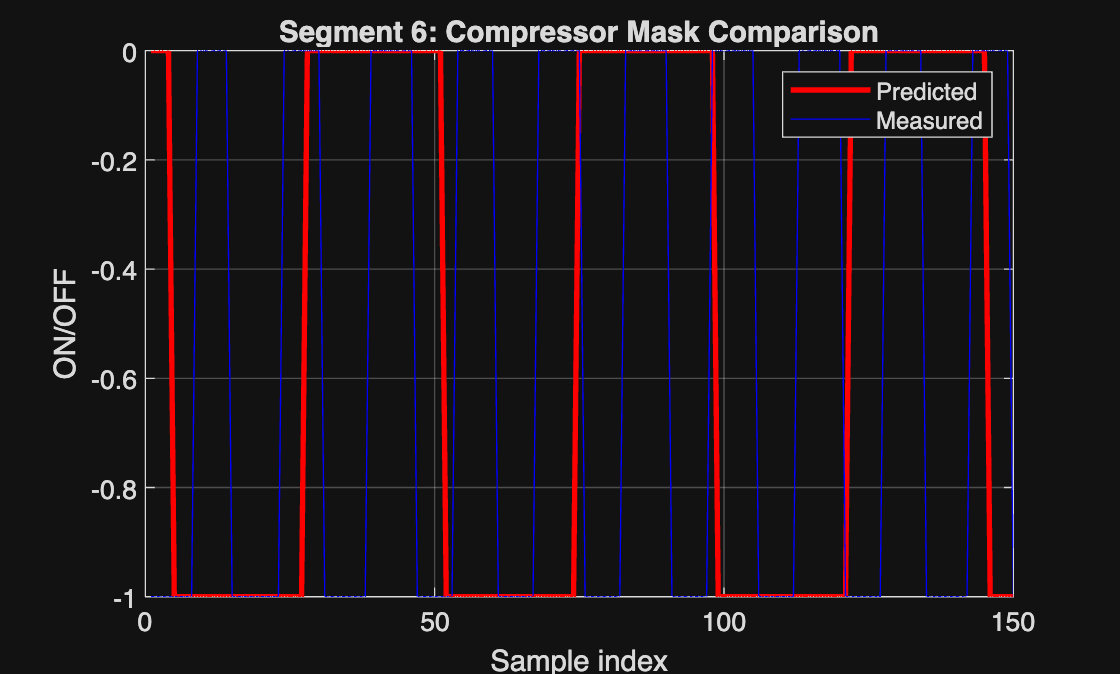

--- Segment 6 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -2.0 s (-2.6%)



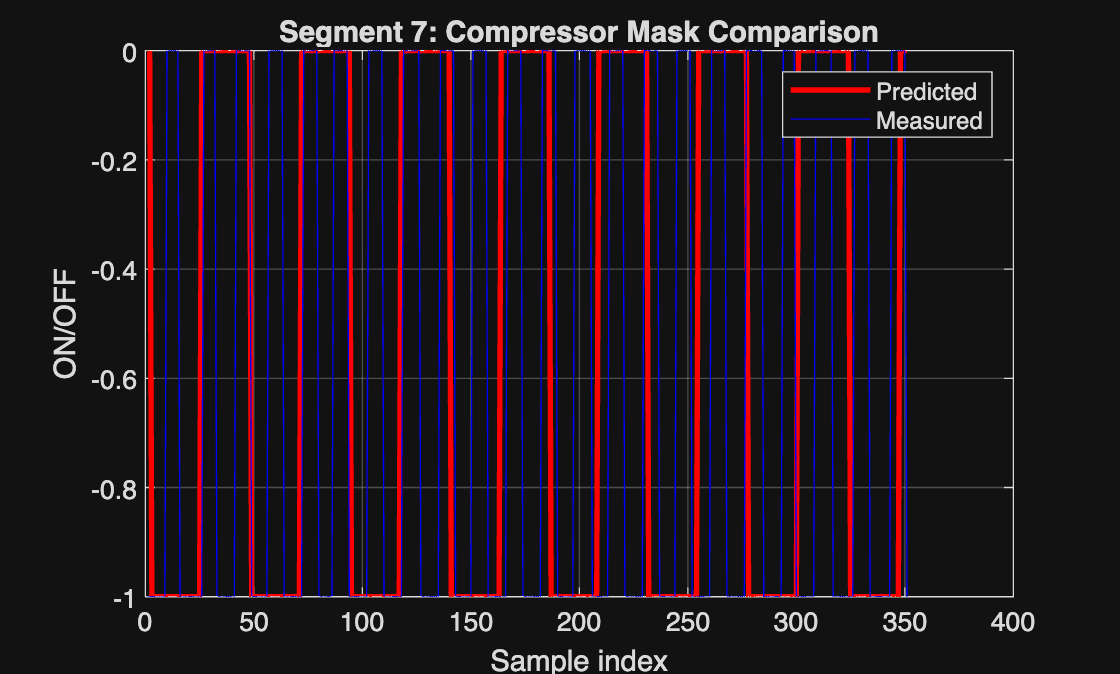

--- Segment 7 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -13.0 s (-6.6%)



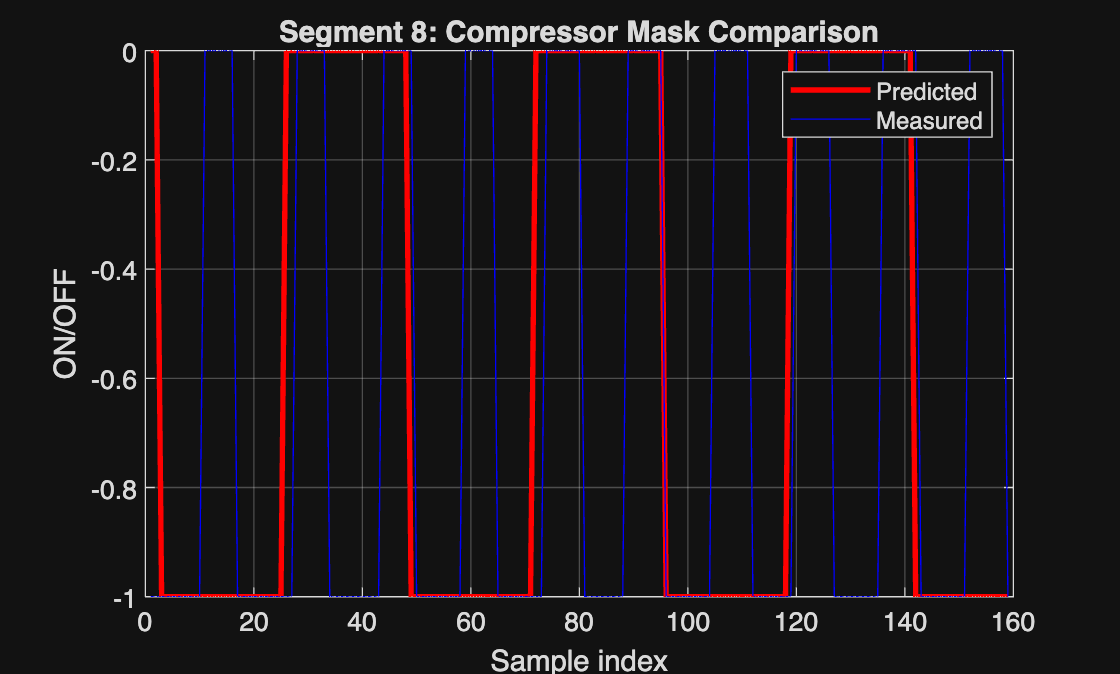

--- Segment 8 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -6.0 s (-6.5%)



results = analyzeCompressorMaskFromGrayBox(compare_container,'plot',true);

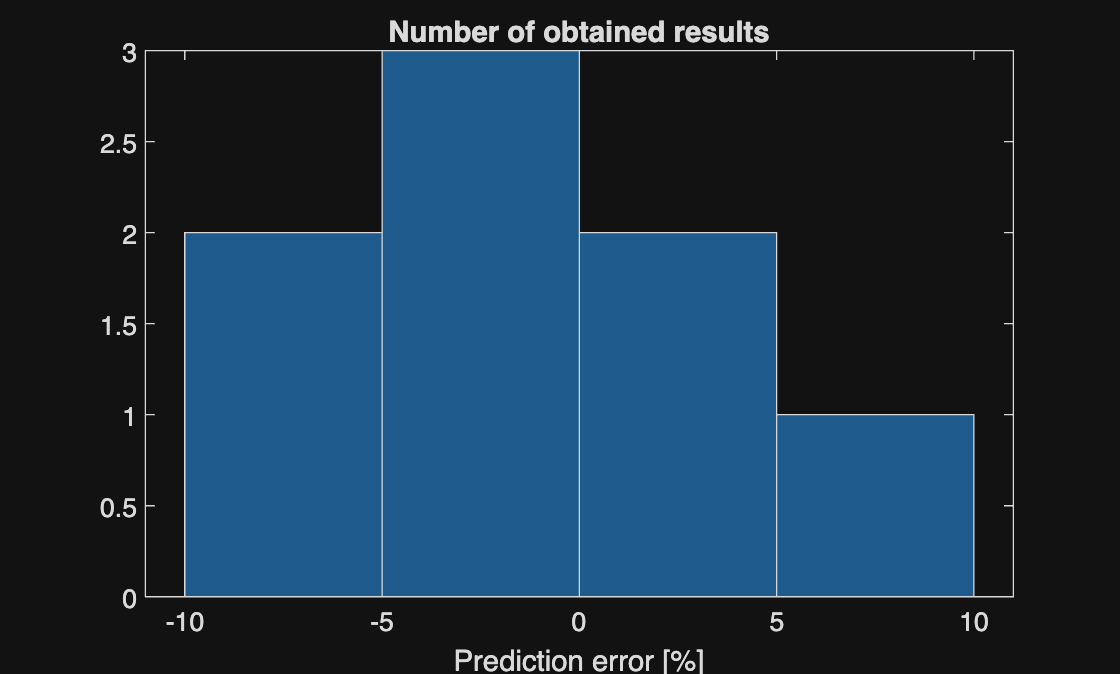

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

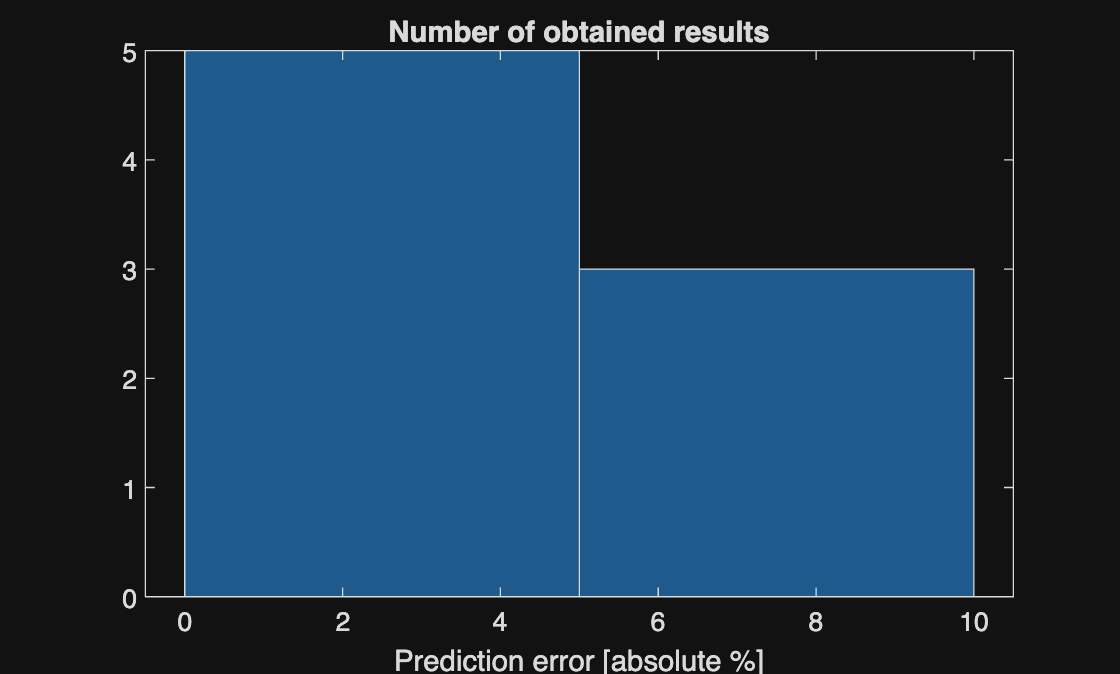

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

idx_badResults = find(abs(pctErrorVector) > 10); 

No results with error > 10%

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   3.4580


function simData = fridge_fixed_stepCopy(Ta,G,R,c,t,x0)
% Discrete-time simulation of a refrigerator with hysteresis control
% ––– USER DEFINED SYSTEM ––– ------------------------------------------

% G=2.1686;   
% R=48.9120; 
% c=114.2959;

A=-1/(R*c);
B=[G/c,1/(R*c)];
C=1;
D=[0,0];

dt     = t(2)-t(1);                % time step [s]
Tend   = t(end);           % simulate 2 hours
% t      = 0:dt:Tend;        % time vector
Ta_fun = @(t) Ta((t/dt)+1);  % outdoor temperature

n   = size(A,1);
x   = zeros(n,length(t));
% x0  = zeros(n,1);         % initial state
x(:,1) = x0;

y  = zeros(1,length(t));
u1 = zeros(1,length(t));
u2 = arrayfun(Ta_fun, t);

% ––– Hysteresis controller state
heater = 0;               % compressor OFF initially
T_low  = -22.5;               % °C, turn ON below this
T_high = -19.5;               % °C, turn OFF above this

% ––– MAIN LOOP ––– -----------------------------------------------------
for k = 1:length(t)-1
    y(k) = C*x(:,k) + D*[u1(k); u2(k)];

    % Controller logic (hysteresis)
    if y(k) < T_low
        heater = 0;
    elseif y(k) > T_high
        heater = -1;
    end
    u1(k+1) = heater;

    % Plant update (Euler integration)
    u = [u1(k); u2(k)];
    dx = A*x(:,k) + B*u;
    x(:,k+1) = x(:,k) + dt * dx;
end
y(end) = C*x(:,end) + D*[u1(end); u2(end)];

% ––– OUTPUT ––– --------------------------------------------------------

simData = struct('t',t,'x',x,'y',y,'u1',u1,'u2',u2);

% figure
% subplot(3,1,1)
% plot(t/60,y,'LineWidth',1.5), grid on
% ylabel('Fridge T [°C]')
% 
% subplot(3,1,2)
% stairs(t/60,u1,'LineWidth',1.5), grid on
% ylabel('Compressor [0/1]')
% 
% subplot(3,1,3)
% plot(t/60,u2,'LineWidth',1.3), grid on
% xlabel('Time [min]')
% ylabel('Outdoor T_a [°C]')
end